# Plotting LIDAR in Sensor Frame

Using the Simulator, get the CreateRobot object that represents the current state of the robot and read the LIDAR data. 

%Initialize, get LIDAR Constants
angRangeLidar = robotObj.angRangeLidar;
rangeLidar = robotObj.rangeLidar;
numPtsLidar = robotObj.numPtsLidar;
angleData= robotObj.angleArray; 

% Get LIDAR data, this is a row vector with length = numPtsLid
distLidar= genLidar(robotObj);

range2xy takes in the angle and range data and transforms it to x and y coordinates in the sensor's frame. Test your completed function by running the code below. This code plots converts the LIDAR output to x-y cooridnates in teh sensor frame then plots the x-y cooridnates in black. The red dashed line plots the sensor footprint of the LIDAR. NOTE: this plot is in the sensor reference frame

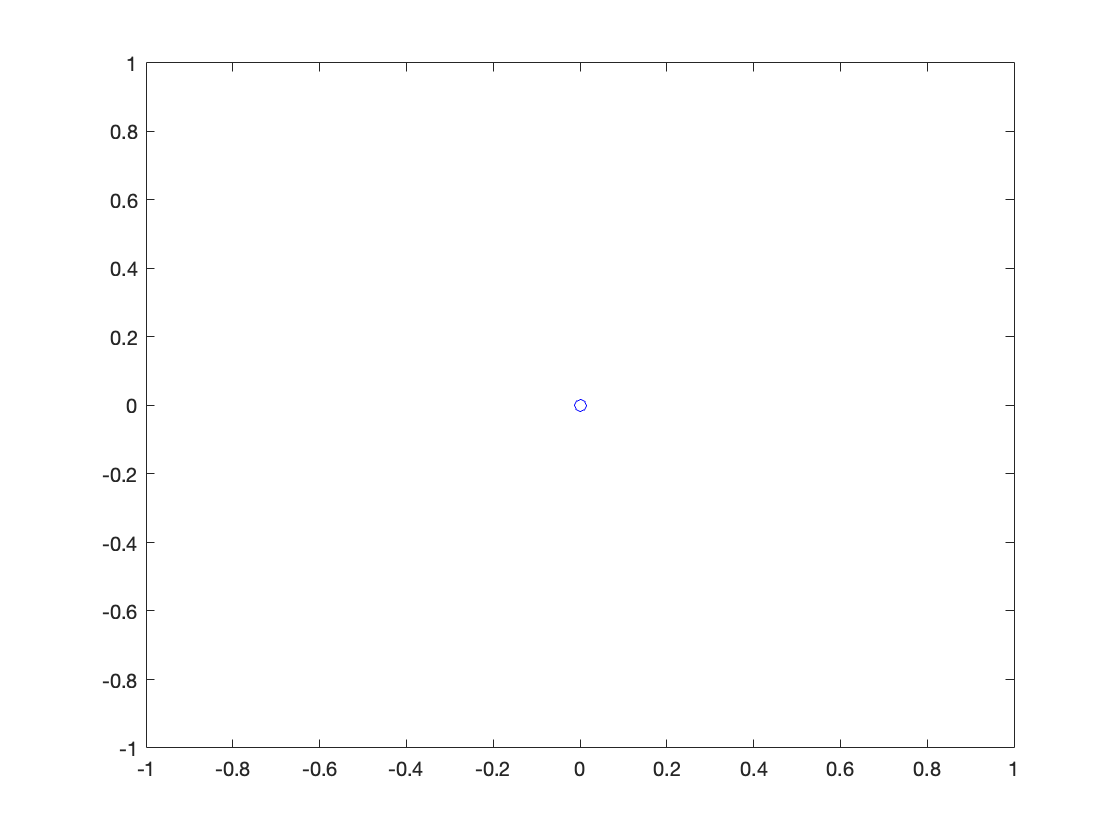

figure; 
depthXY = range2xy(angleData',distLidar',4); % Use your function to convert the data

plot(0,0, 'bo'); %Plot sensor pose in sensor frame

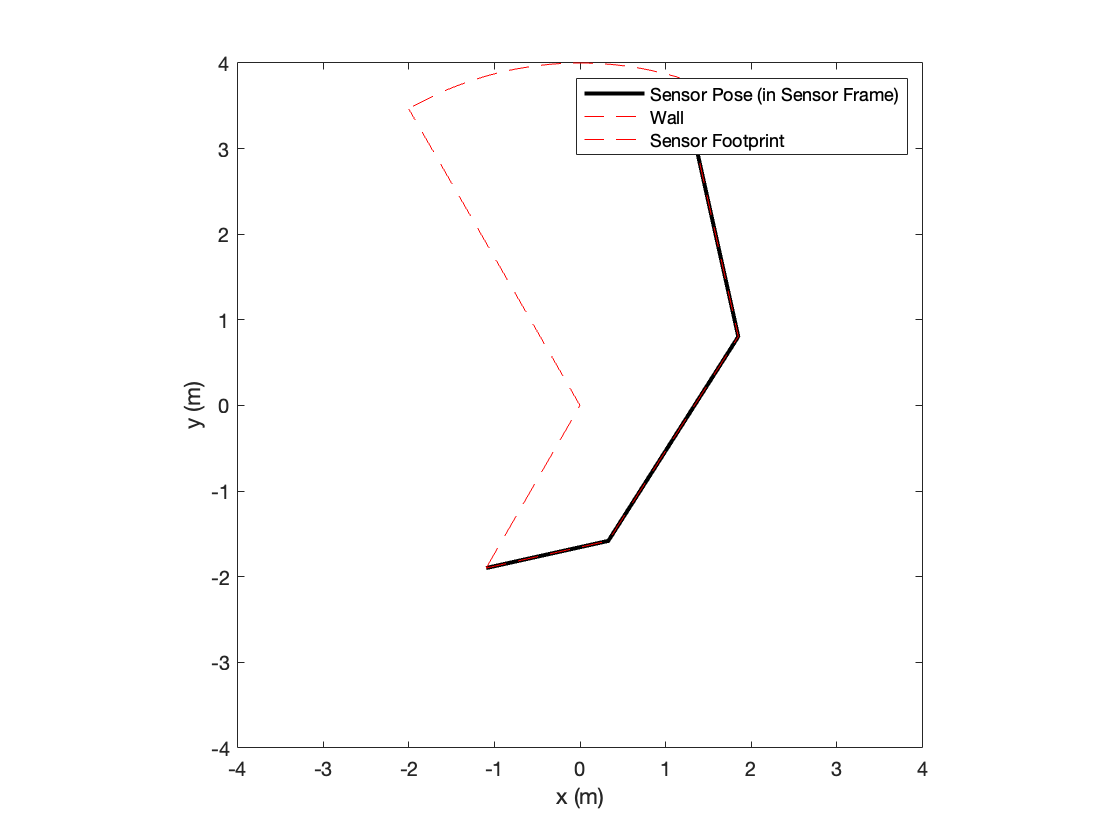

plot(depthXY(1,:),depthXY(2,:),'k','linewidth',2); % Plot the data
axis equal % This line makes the x and y axis have the same scale
axis([-4 4 -4 4])

hold on; %This keeps what has already been plotted if new plots are called
polar(angleData,distLidar,'r--'); %This is similar to plot, but uses polar coordinates. The 'r--' makes the line a red dashed line
polar([lidar(1,1),lidar(1,1),lidar(end,1),lidar(end,1)],[lidar(1,2),0,0,lidar(end,2)],'r--'); %TO DO: Change this to circle

legend( 'Sensor Pose (in Sensor Frame)','Wall', 'Sensor Footprint'); 
xlabel('x (m)')
ylabel('y (m)')

title('plot_LIDAR_xy_sensor')